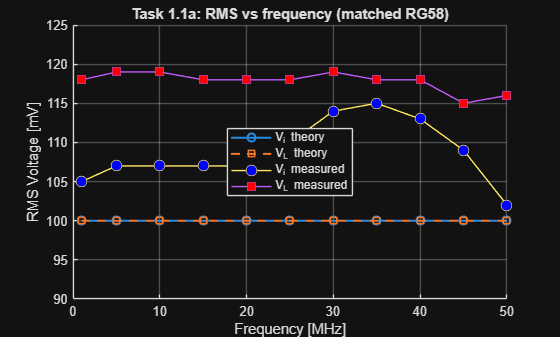

%TASK 1.1a
% --- Data ---
f_MHz = [1 5 10 15 20 25 30 35 40 45 50];
Vi_mV = [105 107 107 107 107 110 114 115 113 109 102];
VL_mV = [118 119 119 118 118 118 119 118 118 115 116];
phi_deg_meas = [4 18 40 58 76 98 112 132 150 167 180];

% --- Theory parameters ---
ell = 2.06;                 % [m] DUT length
VF  = 0.66;                 % RG58 velocity factor
up  = VF*3e8;               % [m/s]
tau = ell/up;               % [s] ~ 10 ns

% --- Theory curves at the SAME frequencies as measured ---
Vi_th = 100 * ones(size(f_MHz));   % [mV], matched divider
VL_th = Vi_th;                     % same (lossless)
phi_deg_th = 360 * (f_MHz*1e6) * tau;  % [deg]

% --- Plot RMS voltages ---
figure; hold on; grid on;
plot(f_MHz, Vi_th, 'o-', 'LineWidth',1.5);
plot(f_MHz, VL_th, 's--', 'LineWidth',1.5);
plot(f_MHz, Vi_mV, 'o-', 'MarkerSize',8, 'MarkerFaceColor','b');
plot(f_MHz, VL_mV, 's-', 'MarkerSize',8, 'MarkerFaceColor','r');
xlabel('Frequency [MHz]'); ylabel('RMS Voltage [mV]');
legend('V_i theory','V_L theory','V_i measured','V_L measured','Location','best');
title('Task 1.1a: RMS vs frequency (matched RG58)');
ylim([90 125]);

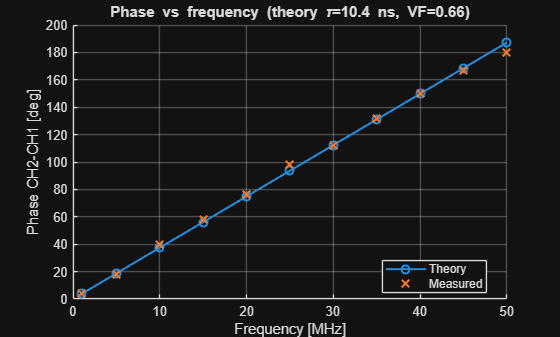


% --- Plot phase ---
figure; hold on; grid on;
plot(f_MHz, phi_deg_th, 'o-', 'LineWidth',1.5);
plot(f_MHz, phi_deg_meas, 'x', 'MarkerSize',8, 'LineWidth',1.5);
xlabel('Frequency [MHz]'); ylabel('Phase CH2-CH1 [deg]');
title(sprintf('Phase vs frequency (theory \\tau=%.1f ns, VF=%.2f)', ...
              tau*1e9, VF));
legend('Theory','Measured','Location','best');

%TASK 1.2a
%% --- Known setup ---
Z0  = 50;            % [ohm]
Zg  = 50;            % [ohm] source
Vg  = 0.200;         % [V_rms] source setting (adjust if your lab used another)
ell = 2.06;          % [m] DUT (incl. connectors) – use what you measured
VF  = 0.66;          % RG58 velocity factor – or use your fitted VF from 1.1
up  = VF*3e8;        % [m/s]

%% --- Your measured data (fill in) ---
% Use the same frequency grid for Vi and VL in each case.

% OPEN CIRCUIT:
f_OC_MHz  = [1 5 10 15 20 25 30 35 40 45 50];
Vi_OC_mV  = [295 188 160 106 30.3 36 111 170 206 197 165];
VL_OC_mV  = [206 212 219 216 206 198 208 223 219 198 178];

% SHORT CIRCUIT:
f_SC_MHz  = [1 5 10 15 20 25 30 35 40 45 50];
Vi_SC_mV  = [15.5 77 126 168 198 206 285 140 95.5 33.7 28.9];
VL_SC_mV  = [1.2 2 3.2 8 9 10.5 11.5 12 12.9 14.5 17.2];

% 25 ohm:
f_25_MHz  = [1 5 10 15 20 25 30 35 40 45 50];
Vi_25_mV  = [79.5 88 106 124 137 141 134 116 97 82.3 80.5];
VL_25_mV  = [95.5 96 91.5 91.5 91.5 92.5 91.5 90 89.5 90 91.6];

%% --- Helpers: Zin, ABCD, and theory for Vi & VL ---
Zin_at = @(f, ZL) local_Zin(f, ZL, Z0, ell, up);
ABCD   = @(f) local_ABCD(f, Z0, ell, up);

% Theory Vi from source divider: Vi = Vg * Zin / (Zg + Zin)
Vi_theory = @(f_MHz, ZL) abs( Vg .* arrayfun(@(fm) ...
                     Zin_at(fm*1e6, ZL) / (Zg + Zin_at(fm*1e6, ZL)), f_MHz) );

% Theory VL from ABCD + input current:
% [V_L; I_L] = [D -B; -C A] [V_i; I_i];  with I_i = Vi / Zin
VL_theory = @(f_MHz, ZL) arrayfun(@(fm)

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

    local_VL_from_Vi(fm*1e6, ZL, Z0, ell, up, Vg, Zg), f_MHz );

% x-axis: distance to load in wavelengths, x = f*ell/up
x_of = @(f_MHz) (f_MHz*1e6) * ell / up;

%% --- THEORY curves (at your measured freqs), converted to mV ---
Vi_OC_th_mV = 1e3 * Vi_theory(f_OC_MHz, Inf);
Vi_SC_th_mV = 1e3 * Vi_theory(f_SC_MHz, 0);
Vi_25_th_mV = 1e3 * Vi_theory(f_25_MHz, 25);

VL_OC_th_mV = 1e3 * abs(VL_theory(f_OC_MHz, Inf));
VL_SC_th_mV = 1e3 * abs(VL_theory(f_SC_MHz, 0));
VL_25_th_mV = 1e3 * abs(VL_theory(f_25_MHz, 25));

%% --- X-axes (electrical distance) ---
x_OC  = x_of(f_OC_MHz);
x_SC  = x_of(f_SC_MHz);
x_25  = x_of(f_25_MHz);

%% --- PLOTS: Vi vs distance (all three terminations) ---
figure; hold on; grid on;
plot(x_OC, Vi_OC_th_mV,  '-', 'LineWidth',1.5);
plot(x_OC, Vi_OC_mV,     'o', 'MarkerSize',7, 'MarkerFaceColor','w');
plot(x_SC, Vi_SC_th_mV,  '-', 'LineWidth',1.5);
plot(x_SC, Vi_SC_mV,     's', 'MarkerSize',7, 'MarkerFaceColor','w');
plot(x_25, Vi_25_th_mV,  '-', 'LineWidth',1.5);
plot(x_25, Vi_25_mV,     'd', 'MarkerSize',7, 'MarkerFaceColor','w');
xlabel('Distance to load, x = \ell/\lambda [wavelengths]');
ylabel('|V_i| [mV RMS]');
legend('Open (theory)','Open (meas)', ...
       'Short (theory)','Short (meas)', ...
       '25 \Omega (theory)','25 \Omega (meas)', ...
       'Location','best');
title(sprintf('|V_i| vs distance (\\ell=%.2f m, VF=%.2f)', ell, VF));

%% --- PLOTS: VL vs distance (all three terminations) ---
figure; hold on; grid on;
plot(x_OC, VL_OC_th_mV,  '-', 'LineWidth',1.5);
plot(x_OC, VL_OC_mV,     'o', 'MarkerSize',7, 'MarkerFaceColor','w');
plot(x_SC, VL_SC_th_mV,  '-', 'LineWidth',1.5);
plot(x_SC, VL_SC_mV,     's', 'MarkerSize',7, 'MarkerFaceColor','w');
plot(x_25, VL_25_th_mV,  '-', 'LineWidth',1.5);
plot(x_25, VL_25_mV,     'd', 'MarkerSize',7, 'MarkerFaceColor','w');
xlabel('Distance to load, x = \ell/\lambda [wavelengths]');
ylabel('|V_L| [mV RMS]');
legend('Open (theory)','Open (meas)', ...
       'Short (theory)','Short (meas)', ...
       '25 \Omega (theory)','25 \Omega (meas)', ...
       'Location','best');
title(sprintf('|V_L| vs distance (\\ell=%.2f m, VF=%.2f)', ell, VF));

%% ---- Local functions (place AFTER the script body) ----
function Zin = local_Zin(f, ZL, Z0, ell, up)
    beta = 2*pi*f/up;
    if isinf(ZL)           % Open
        Zin = -1j*Z0*cot(beta*ell);
    elseif ZL==0           % Short
        Zin =  1j*Z0*tan(beta*ell);
    else                   % General
        Zin = Z0*(ZL + 1j*Z0*tan(beta*ell)) / (Z0 + 1j*ZL*tan(beta*ell));
    end
end

function [A,B,C,D] = local_ABCD(f, Z0, ell, up)
    beta = 2*pi*f/up;
    A = cos(beta*ell);
    B = 1j*Z0*sin(beta*ell);
    C = 1j*(1/Z0)*sin(beta*ell);
    D = cos(beta*ell);
end

function VL = local_VL_from_Vi(f, ZL, Z0, ell, up, Vg, Zg)
    % compute Vi from source divider
    Zin = local_Zin(f, ZL, Z0, ell, up);
    Vi  = Vg * Zin/(Zg + Zin);
    Ii  = Vi / Zin;
    % back-propagate to load with inverse ABCD: [V_L; I_L] = [D -B; -C A][V_i; I_i]
    [A,B,C,D] = local_ABCD(f, Z0, ell, up);
    VL = D*Vi - B*Ii;   % complex; we take magnitude outside
end




%TASK 1.3a
Z0  = 50;
ell = 2.01;          % m (your measured cable+connectors)
up  = 0.66*3e8;      % m/s (or compute from your measured Δf)
% ---- Measured extrema ----
Vi_max_mV = 139;           % e.g., [132 129 131]
f_max_MHz = 48;           % their frequencies
Vi_min_mV = 80;           % e.g., [88 90 89]
f_min_MHz = 24;           % their frequencies

% --- VSWR & |Gamma| ---
S = Vi_max_mV / Vi_min_mV;  
rho = (S-1)/(S+1);             % |Gamma_L|

% --- Angle of Gamma from one (or average of many) maxima ---
fm = mean(f_max_MHz)*1e6;      % Hz
ang = mod(4*pi*ell*fm/up, 2*pi);  % radians, using a MAX
% If you used a MIN instead, do: ang = mod(4*pi*ell*fm/up + pi, 2*pi);

GammaL = rho * exp(1j*ang);    % complex reflection coefficient
ZL = Z0 * (1 + GammaL) / (1 - GammaL);

fprintf('VSWR S=%.3f, |Gamma|=%.3f, angle=%.1f deg\n', S, rho, rad2deg(ang));

VSWR S=1.738, |Gamma|=0.269, angle=350.8 deg


fprintf('Estimated load: ZL = %.2f %+.2fj ohms\n', real(ZL), imag(ZL));

Estimated load: ZL = 85.77 -7.94j ohms
